# **drawCanoe**

# **drawCanoe1**

# **fillCanoe**

# **fillCanoe1**

Draw or fill  canoe i.e. rectangle with rounded ends.

## Description

Canoe is IGES flash entity,  form number 4. (see [1], pp 120,123)

## Syntax

drawCanoe(wd,ht,xr,yr)

drawCanoe(wd,ht,xr,yr,rot)

drawCanoe1( ht,x1,y1,x2,y2)

drawcanoe1(ht,x1,y1,'-delta',dx,dy)

drawCanoe1(ht,x1,y1,'-polar',r,th)

drawCanoe(__,'-pos',ip)

drawCanoe(__,'-np',np)

drawCanoe(__,LineSpec)

p = drawCanoe(__)

fillCanoe(c,__)

### Description

drawCanoe(wd,ht,xr,yr,rot) draw canoe of length wd and height ht rotated by given angle *rot *about reference point *xr*,*yr*. 

drawCanoe(wd,ht,xr,yr,rot,'-pos',ip) draw canoe with reference point at position ip:1,...,11, (def. is 5, i.e., canoe center)

drawCanoe(__,LineSpec)  sets the line style.

p = drawCanoe(__) returns some output data.

### Method

For calculation of the coordinates of the drawCanoe call the function **evalRect **and **evalCircle**.

## Arguments

### Input Arguments

**c        **- fill color (for fillCanoe)

**wd       **- width

**ht       **- height

**xr, yr   **- reference point 

**rot **- rotation angle about the reference point  in degrees

or for drawCanoe1

**x1, y1 - **start point (key point 4)

**x2, y2 - **end point (key point 6)

or instaed of x2,y2

**'-rtheta',r,th **- polar coordinates of end point from start point

or

**'-delta',dx,dy **- shift vector

### Optional Name-Value Pair Input Arguments

**'-pos',ip **- position of reference point:1,...,11 (default is 5, i.e. center) (see Example 2)

***LineSpec*** - specifies line properties, see [Line Properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html).

### Optional Output Arguments

**p **- structure .

-  p.wd  - width;

-  p.ht    - height;

- p.x - x-coordinates of the reference points (real column vector)

- p.y - y coordinates of the reference points  (real column vector)

- p.style - line style 

- p.width - line width 

- p.color - line color

*Note. Rectangle* is closed so x(end) = x(1) and y(end) = y(1).

## Examples

### Example 1

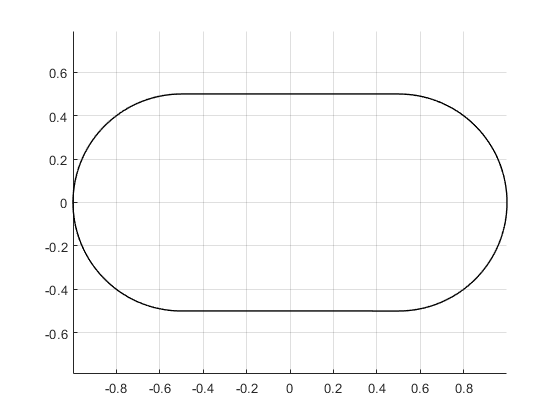

figure
hold on
axis equal
% close polygon
drawCanoe( 2, 1,0,0,0);
grid on

#### **Example 2**

figure
axis equal
hold on
% plot definiting polygon
p=drawCanoe(2,1,0,0,0,'r:')

p = struct with fields:
       xk: [11×1 double]
       yk: [11×1 double]
    color: [1 0 0]


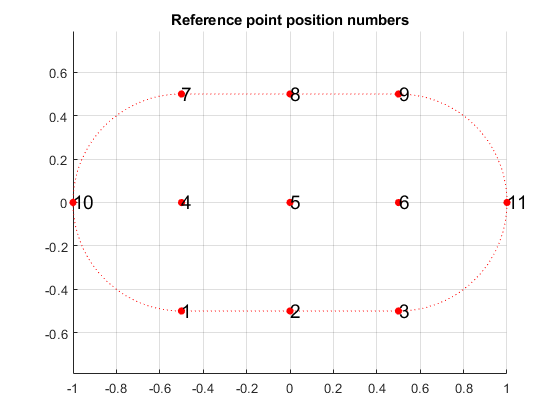

% plot referebnce points
scatter(p.xk,p.yk,30,'r','filled')
for k = 1:length(p.xk)
    text(p.xk(k),p.yk(k),num2str(k),'FontSize',14)
end
title('Reference point position numbers')
grid on

#### **Example 3**

figure
axis equal
hold on
ip = 6; % rotation about position point
p=drawCanoe(4,3,0,0,-12,'-pos',ip,'-np',100)

p = struct with fields:
       xk: [11×1 double]
       yk: [11×1 double]
    color: 'k'


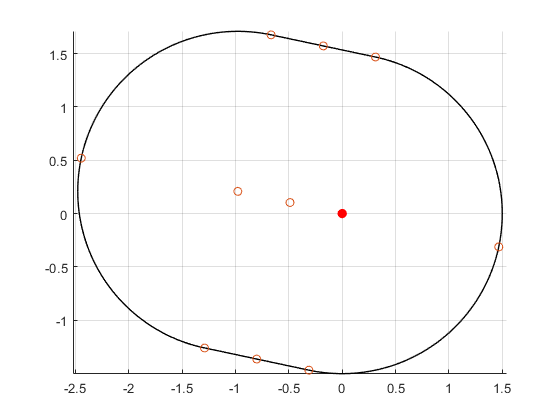

scatter(p.xk,p.yk)
scatter(p.xk(ip),p.yk(ip),50,'r','filled')
grid on

### Example 4

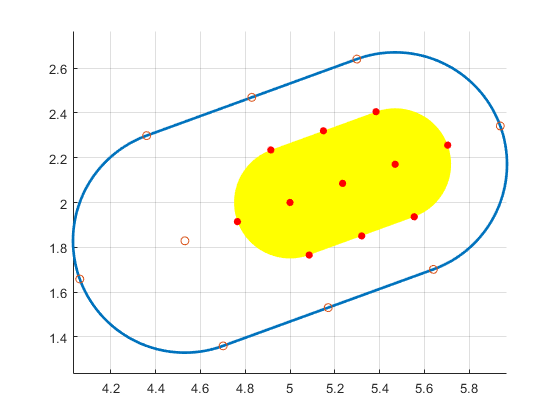

figure
axis equal
hold on
r1=drawCanoe(2,1,5,2,20,'LineWidth',2);
scatter(r1.xk,r1.yk)
r2=fillCanoe('y',1,0.5,r1.xk(5),r1.yk(5),20,'-pos',4);
scatter(r2.xk,r2.yk,30,'r','filled')
grid on

### Example 5

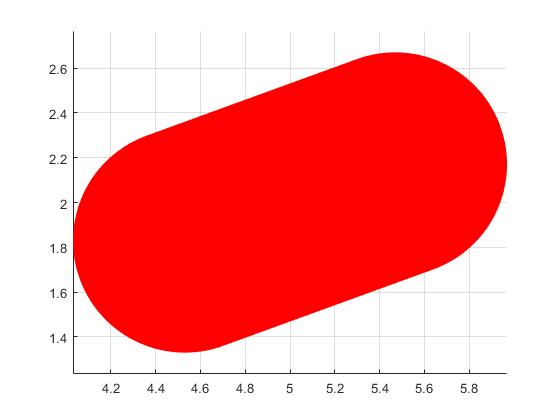

figure
axis equal
hold on
r1=fillCanoe('r',2,1,5,2,20);
grid on

### Example 6

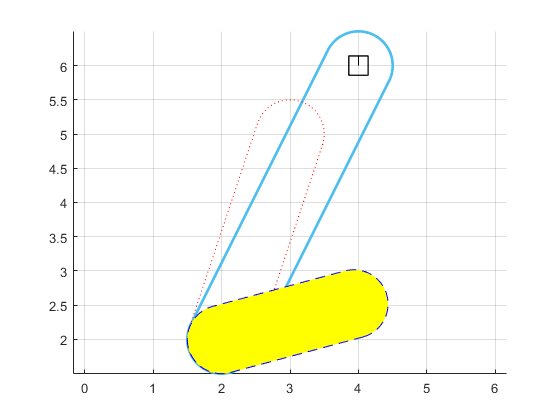

figure
axis equal
hold on
x1 = 2; y1 = 2;
x2 = 4; y2 = 6;
drawPoint(1,0.4,x1,y1)
drawPoint(2,0.4,x2,y2)
drawCanoe1(1,x1,y1,x2,y2,'LineWidth',2);
drawCanoe1(1,x1,y1,'-delta',1,3,'r:');
fillCanoe1('y',1,x1,y1,'-polar',2,15);
drawCanoe1(1,x1,y1,'-polar',2,15,'b--');
grid on

## See also

## References

  [1] [IGES Initial Graphics Exchange Specification IGES 5.3](http://paulbourke.net/dataformats/iges/IGES.pdf)